load("DREAMER.mat"); % load DREAMER dataset

## Basic Vars

samplingRate = DREAMER.EEG_SamplingRate; % retrieve sampling rate
windowSize = 256; % window size for each data segment in PSD (power spectral density) calculation
overlap = 128; % overlap between segments

freqRanges = [
    4, 8;      % Theta band: 4 - 8 Hz
    8, 13;     % Alpha band: 8 - 13 Hz
    13, 20;    % Beta band: 13 - 20 Hz
];

## Subject 1 Film 1 Test

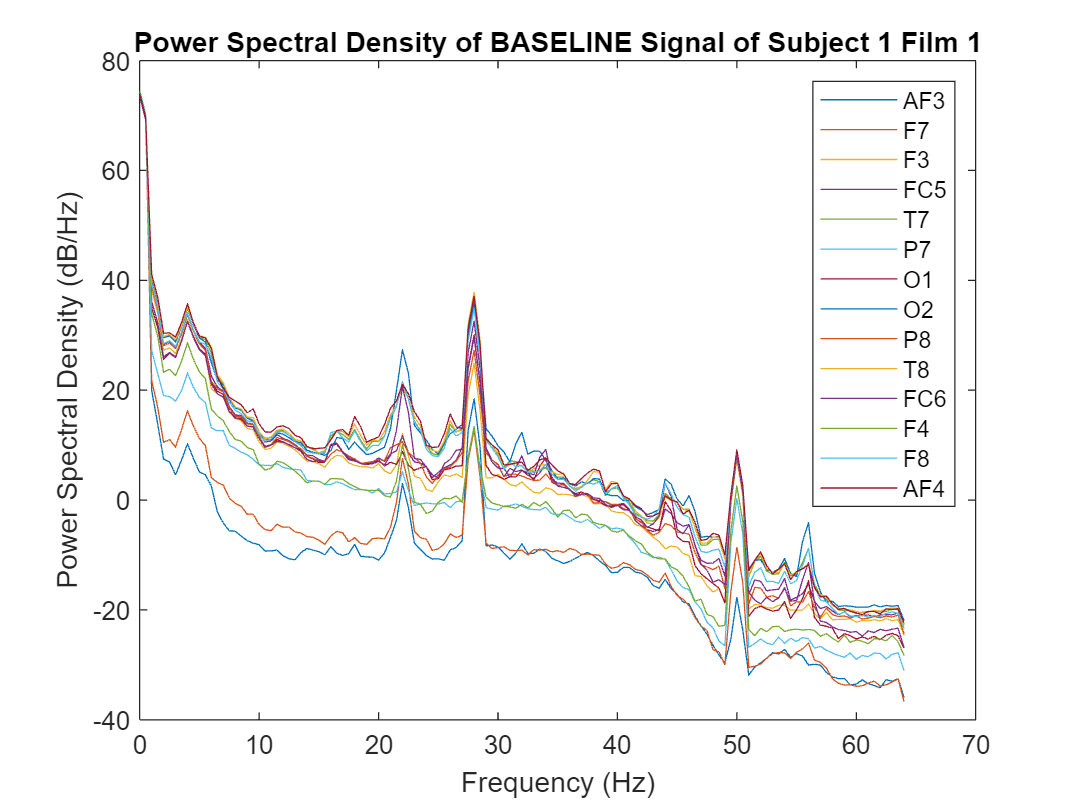

% baseline feature extraction (last 60s)
EEG_baseline = DREAMER.Data{1}.EEG.baseline{1}; % load baseline EEG signal for subject 1 film 1
baseline_last_60s = EEG_baseline(end-samplingRate*60+1:end, :);
[psd, freq] = getPSD(baseline_last_60s, windowSize, overlap, samplingRate);
graphPSD(freq, psd, 'baseline', 1, 1, DREAMER.EEG_Electrodes);

baseline_features = extractEEGFeatures(freq, psd, freqRanges);

% verification
psd, freq, baseline_features

psd = 1.0e+07 *

    2.7993    2.4427    2.5132    2.7952    2.6748    2.7978    2.8423    2.2960    2.7006    2.6315    2.2622    2.8552    2.6661    2.5337
    1.0262    0.8955    0.9200    1.0230    0.9789    1.0262    1.0419    0.8410    0.9883    0.9631    0.8286    1.0456    0.9758    0.9269
    0.0000    0.0000    0.0007    0.0009    0.0011    0.0001    0.0003    0.0011    0.0008    0.0012    0.0004    0.0002    0.0009    0.0013
    0.0000    0.0000    0.0003    0.0003    0.0004    0.0000    0.0001    0.0004    0.0003    0.0005    0.0002    0.0001    0.0003    0.0005
    0.0000    0.0000    0.0001    0.0001    0.0001    0.0000    0.0000    0.0001    0.0001    0.0001    0.0000    0.0000    0.0001    0.0001
    0.0000    0.0000    0.0001    0.0001    0.0001    0.0000    0.0000    0.0001    0.0001    0.0001    0.0000    0.0000    0.0001    0.0001
    0.0000    0.0000    0.0000    0.0001    0.0001    0.0000    0.0000    0.0001    0.0001    0.0001    0.0000    0.0000    0.0001    0.0

freq =          0
    0.5000
    1.0000
    1.5000
    2.0000
    2.5000
    3.0000
    3.5000
    4.0000
    4.5000


baseline_features =    13.0754   18.7006   35.1290   36.2960   37.6232   26.2284   35.0669   37.3693   36.0357   37.9058   34.9307   30.9238   36.7146   38.0420
    1.5863    6.4157   21.6561   22.7123   23.6502   17.0748   22.0834   23.4103   22.4221   23.8055   22.0176   17.9939   23.2096   24.7846
    1.9071    4.6210   18.5066   19.6809   22.2269   14.5509   19.5607   21.0417   19.4169   22.5877   19.4817   14.6521   21.9612   23.1774


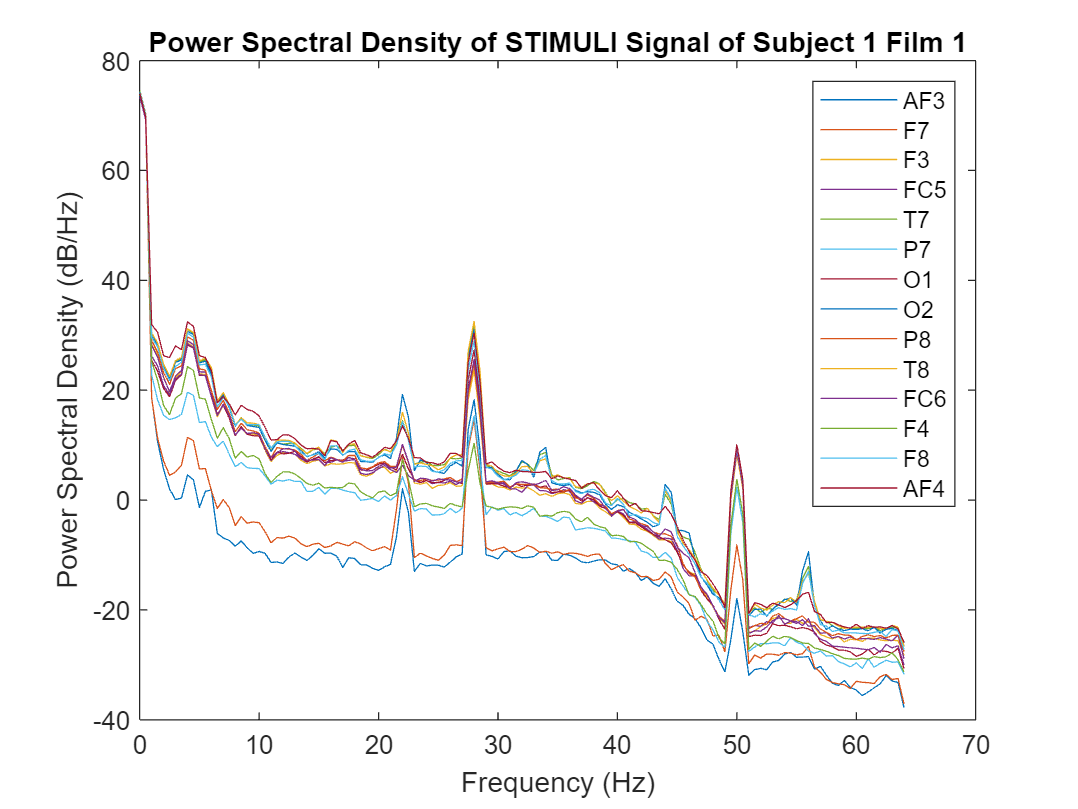


% stimuli feature extraction (last 60s)
EEG_stimuli = DREAMER.Data{1}.EEG.stimuli{1}; % load stimuli EEG signal for subject 1 film 1
stimuli_last_60s = EEG_stimuli(end-samplingRate*60+1:end,:);
[psd, freq] = getPSD(stimuli_last_60s, windowSize, overlap, samplingRate);
graphPSD(freq, psd, 'stimuli', 1, 1, DREAMER.EEG_Electrodes);

stimuli_features = extractEEGFeatures(freq, psd, freqRanges);
stimuli_features_normalized = stimuli_features./baseline_features;

stimuli_features, stimuli_features_normalized

stimuli_features =     9.1270   14.8426   31.9714   32.3919   34.5493   23.4853   31.7656   34.2586   33.0278   34.7504   31.8329   27.6608   33.8204   35.5372
    0.3477    4.7753   20.5029   20.6558   22.3127   14.9038   20.5729   22.1396   21.2403   22.5879   20.7852   16.4890   22.4098   24.3757
    0.8512    3.2982   17.9045   18.2979   20.5279   13.0687   18.5850   19.8099   18.9242   20.7810   18.4602   13.9855   19.9236   21.0184


stimuli_features_normalized =     0.6980    0.7937    0.9101    0.8924    0.9183    0.8954    0.9059    0.9168    0.9165    0.9168    0.9113    0.8945    0.9212    0.9342
    0.2192    0.7443    0.9468    0.9095    0.9434    0.8729    0.9316    0.9457    0.9473    0.9489    0.9440    0.9164    0.9655    0.9835
    0.4463    0.7137    0.9675    0.9297    0.9236    0.8981    0.9501    0.9415    0.9746    0.9200    0.9476    0.9545    0.9072    0.9068


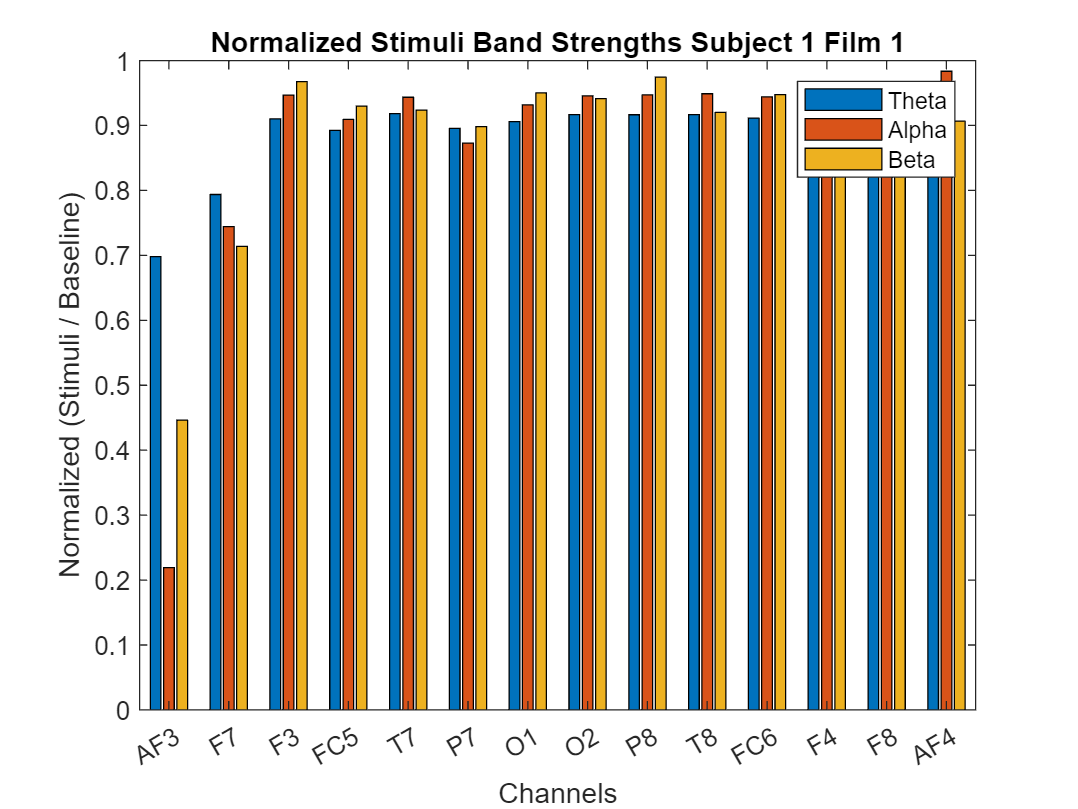


% normalized feature graph
graphFeatures(stimuli_features_normalized, 1, 1, DREAMER.EEG_Electrodes);

## Subject 1 Film 2 Test

% baseline feature extraction (last 60s)
EEG_1_baseline_2 = DREAMER.Data{1}.EEG.baseline{2};
baseline_last_60s = EEG_1_baseline_2(end-samplingRate*60+1:end, :);
[psd, freq] = getPSD(baseline_last_60s, windowSize, overlap, samplingRate);
baseline_features = extractEEGFeatures(freq, psd, freqRanges);

% stimuli feature extraction (last 60s)
EEG_1_stimuli_2 = DREAMER.Data{1}.EEG.stimuli{2};
stimuli_last_60s = EEG_1_stimuli_2(end-samplingRate*60+1:end,:);
[psd, freq] = getPSD(stimuli_last_60s, windowSize, overlap, samplingRate);
stimuli_features = extractEEGFeatures(freq, psd, freqRanges);
stimuli_features_normalized = stimuli_features./baseline_features;
stimuli_features_normalized

stimuli_features_normalized =     0.9189    0.8272    0.9133    0.9150    0.9322    0.9131    0.9298    0.9324    0.9350    0.9330    0.9267    0.9167    0.9308    0.9442
   -1.8776    0.6000    0.9204    0.9235    0.9307    0.9006    0.9277    0.9396    0.9397    0.9426    0.9445    0.9021    0.9480    0.9462
   -0.0332    0.5858    0.9219    0.9266    0.9608    0.9269    0.9422    0.9500    0.9460    0.9593    0.9431    0.8989    0.9637    0.9355


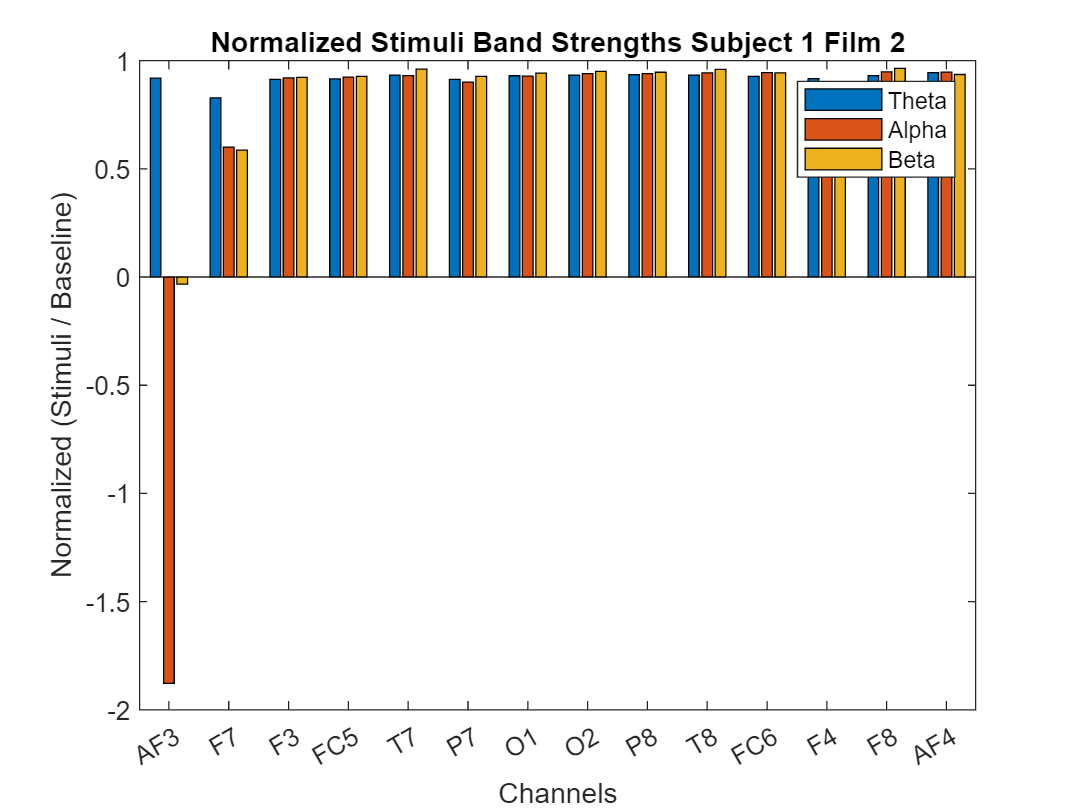


% normalized feature graph
graphFeatures(stimuli_features_normalized, 1, 2, DREAMER.EEG_Electrodes);

## Subject 1 Scores Test

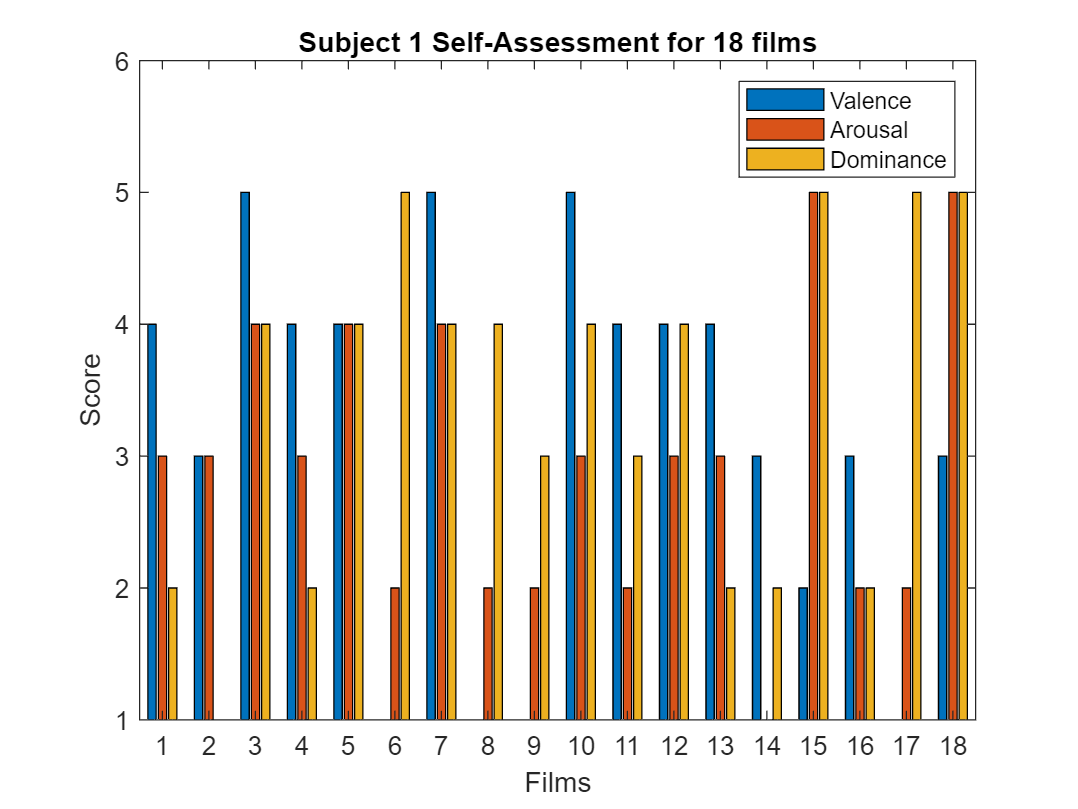

% subject 1 scoring EDA
graphScores(DREAMER, 1);

## Process Data

% compute all features and store in .mat file
features_score = zeros(DREAMER.noOfSubjects*DREAMER.noOfVideoSequences, 43);

for i = 1:DREAMER.noOfSubjects
    for j = 1:DREAMER.noOfVideoSequences
        % baseline feature extraction (last 60s)
        EEG_baseline = DREAMER.Data{i}.EEG.baseline{j};
        baseline_last_60s = EEG_baseline(end-samplingRate*60+1:end, :);
        [psd, freq] = getPSD(baseline_last_60s, windowSize, overlap, samplingRate);
        baseline_features = extractEEGFeatures(freq, psd, freqRanges);

        % stimuli feature extraction (last 60s)
        EEG_stimuli = DREAMER.Data{i}.EEG.stimuli{j};
        stimuli_last_60s = EEG_stimuli(end-samplingRate*60+1:end,:);
        [psd, freq] = getPSD(stimuli_last_60s, windowSize, overlap, samplingRate);
        stimuli_features = extractEEGFeatures(freq, psd, freqRanges);
        stimuli_features_normalized = stimuli_features-baseline_features; % use subtraction because its log values

        features_score((i-1)*DREAMER.noOfVideoSequences+j,1:42) = reshape(stimuli_features_normalized.', 1, []);
    end
end

disp(features_score)

   -3.9484   -3.8579   -3.1575   -3.9041   -3.0739   -2.7430   -3.3013   -3.1107   -3.0079   -3.1554   -3.0978   -3.2630   -2.8942   -2.5048   -1.2386   -1.6404   -1.1531   -2.0564   -1.3375   -2.1710   -1.5104   -1.2707   -1.1818   -1.2176   -1.2324   -1.5049   -0.7997   -0.4088   -1.0560   -1.3228   -0.6021   -1.3830   -1.6990   -1.4822   -0.9757   -1.2318   -0.4927   -1.8066   -1.0214   -0.6666   -2.0376   -2.1590         0
   -0.5470   -2.2208   -2.6112   -2.5580   -2.2253   -1.8870   -2.1015   -2.1981   -2.0383   -2.2162   -2.2099   -2.1637   -2.2419   -1.9281   -0.9412   -1.9412   -1.6364   -1.5797   -1.5701   -1.3091   -1.5097   -1.3542   -1.2967   -1.3248   -1.1691   -1.6415   -1.1839   -1.3236   -0.7973   -1.2363   -1.4112   -1.3478   -0.7875   -0.8373   -1.0787   -0.9985   -1.0252   -0.8327   -1.0669   -1.4544   -0.7283   -1.3741         0
    1.5398    3.6808    3.8559    4.5355    4.3828    4.4410    4.5446    4.2995    4.5534    4.3251    4.5412    4.5400    4.3989    4.09


% save arousal score at the end column for testing
for i = 1:DREAMER.noOfSubjects
    % scoreValence = DREAMER.Data{i}.ScoreValence;
    scoreArousal = DREAMER.Data{i}.ScoreArousal;
    % scoreDominance = DREAMER.Data{i}.ScoreDominance;
    for j = 1:DREAMER.noOfVideoSequences
        features_score((i-1)*DREAMER.noOfVideoSequences+j, 43) = scoreArousal(j);
    end
end

save('features_score.mat', "features_score");

### Function Declarations

function [psd, freq] = getPSD(eegSignal, windowSize, overlap, samplingRate)
    [psd, freq] = pwelch(eegSignal, windowSize, overlap, windowSize, samplingRate); % use Welch's method to calculate PSD
end

function graphPSD(freq, psd, type, subjectId, filmId, channelNames)
    plot(freq, 10*log10(psd)); % convert to dB when graphing
    xlabel('Frequency (Hz)');
    ylabel('Power Spectral Density (dB/Hz)');
    title(compose('Power Spectral Density of %s Signal of Subject %d Film %d', upper(type), subjectId, filmId));
    legend(channelNames);
end

function features = extractEEGFeatures(freq, psd, freqRanges)
    features = zeros(3, 14); % init features with 3 bands and 14 channels
    for i = 1:size(freqRanges)
        curBand = freqRanges(i, :);
        features(i, :) = trapz(psd(freq >= curBand(1) & freq <= curBand(2), :));
    end
    features = 10*log10(features);
end

function graphFeatures(features, subjectId, filmId, channelNames)
    bar(transpose(features), 'grouped');
    xlabel('Channels');
    xticklabels(channelNames);
    ylabel('Normalized (Stimuli / Baseline)');
    title(compose('Normalized Stimuli Band Strengths Subject %d Film %d', subjectId, filmId));
    legend({'Theta', 'Alpha', 'Beta'});
end

function graphScores(DREAMER, subjectId)
    scoreCategories = {'Valence', 'Arousal', 'Dominance'};
    scores = [DREAMER.Data{subjectId}.ScoreValence, DREAMER.Data{subjectId}.ScoreArousal, DREAMER.Data{subjectId}.ScoreDominance]; % load self-assessment scores for subjectId
    bar(scores, 'grouped'); % plot a grouped bar graph with each group representing one of 18 films
    xlabel('Films');
    xticks(1:18);
    ylabel('Score');
    ylim([1,6]);
    yticks(1:6);
    title(compose('Subject %d Self-Assessment for 18 films', subjectId));
    legend(scoreCategories);
end